## **PID regulacija sustava automatskog navodnjavanja**

clc; clear; close all;

## 1.Prijenosna funkcija i stabilnost sustava 

% Parametri sustava za male sadnice
% Mijenjaju se s obzirom na volumen zemlje, vrsti zemlje...

V2 = 200;                % Kontejner 200 ml
ke = 0.0175;               % isparavanje ml/s
k12 = 0.1;               % otjecanje ml/s
kp = 0.6;               %protok pumpe ml/s


%% Prijenosna funkcija G0(s)
s = tf('s');
G0 = (kp * k12) / (V2 * (s + k12) * (s + ke));

disp('Prijenosna funkcija G0(s):');

Prijenosna funkcija G0(s):


G0


G0 =
 
           0.06
  -----------------------
  200 s^2 + 23.5 s + 0.35
 
Continuous-time transfer function.
Model Properties



pole(G0)

ans =    -0.1000
   -0.0175


### Odziv na skok

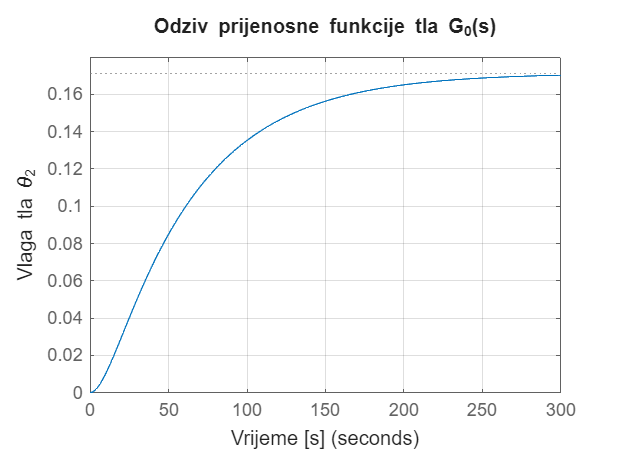

figure;
step(G0, 300);   % 300 s simulacije
grid on;
title('Odziv prijenosne funkcije tla G_0(s)');
xlabel('Vrijeme [s]');
ylabel('Vlaga tla \theta_2');

### Karakteristike odziva

info = stepinfo(G0);

disp('Karakteristike odziva:');

Karakteristike odziva:


fprintf('Vrijeme porasta: %.2f s\n', info.RiseTime);

Vrijeme porasta: 128.89 s


fprintf('Vrijeme stabilizacije: %.2f s\n', info.SettlingTime);

Vrijeme stabilizacije: 234.54 s


fprintf('Maksimalna vrijednost: %.2f\n', info.Peak);

Maksimalna vrijednost: 0.17


fprintf('Nadvišenje: %.2f %%\n', info.Overshoot);

Nadvišenje: 0.00 %


### Odziv na skok

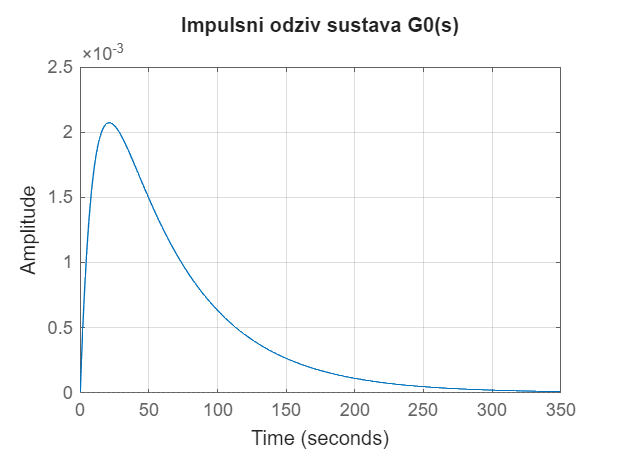

impulse(G0);
grid on;
title('Impulsni odziv sustava G0(s)');

### Provjera nula 

pole(G0)

ans =    -0.1000
   -0.0175


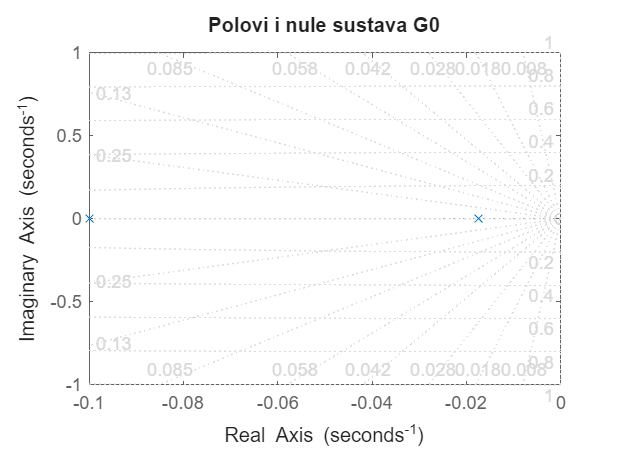


pzmap(G0)   % crtanje polova i nula
grid on
title('Polovi i nule sustava G0')

*Ovaj sustav je stabilan budući da su svi polovi u lijevoj poluravnini.*

## 2. PID parametri

Kp = 0.5;
Ki = 0.05;
Kd = 0.5;
Gr = pid(Kp, Ki, Kd);

disp('PID regulator Gr(s):');

PID regulator Gr(s):


Gr


Gr =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.5, Ki = 0.05, Kd = 0.5
 
Continuous-time PID controller in parallel form.
Model Properties


### Zatvorena petlja, odziv

T_pid = feedback(G0 * Gr, 1);

disp('Zatvorena petlja T_pid(s):');

Zatvorena petlja T_pid(s):


T_pid


T_pid =
 
       0.03 s^2 + 0.03 s + 0.003
  ------------------------------------
  200 s^3 + 23.53 s^2 + 0.38 s + 0.003
 
Continuous-time transfer function.
Model Properties


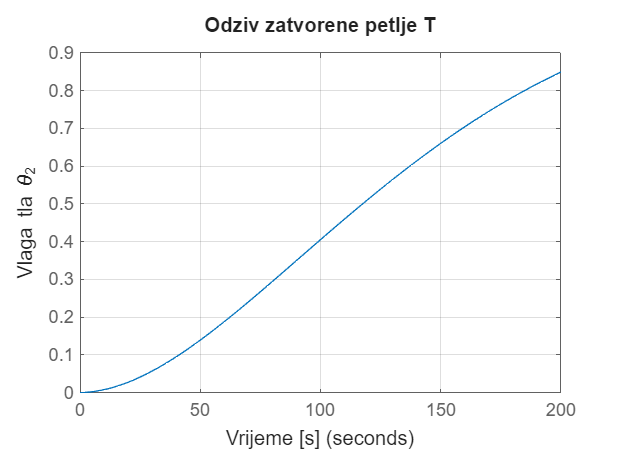


step(T_pid, 200)
grid on;
title('Odziv zatvorene petlje T');
xlabel('Vrijeme [s]');
ylabel('Vlaga tla \theta_2');


info = stepinfo(T_pid);

disp('Karakteristike odziva:');

Karakteristike odziva:


fprintf('Vrijeme porasta: %.2f s\n', info.RiseTime);

Vrijeme porasta: 177.65 s


fprintf('Vrijeme stabilizacije: %.2f s\n', info.SettlingTime);

Vrijeme stabilizacije: 485.70 s


fprintf('Maksimalna vrijednost: %.2f\n', info.Peak);

Maksimalna vrijednost: 1.04


fprintf('Nadvišenje: %.2f %%\n', info.Overshoot);

Nadvišenje: 4.06 %


### Pregled polova za Gr * G0

L = Gr * G0


L =
 
   0.03 s^2 + 0.03 s + 0.003
  ---------------------------
  200 s^3 + 23.5 s^2 + 0.35 s
 
Continuous-time transfer function.
Model Properties


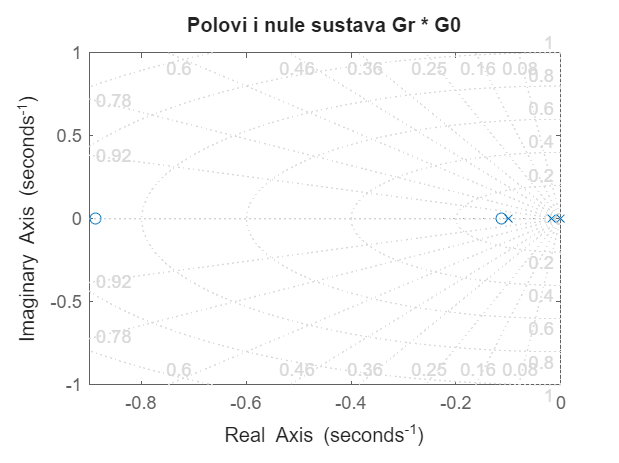

pzmap(L)   % crtanje polova i nula
grid on
title('Polovi i nule sustava Gr * G0')

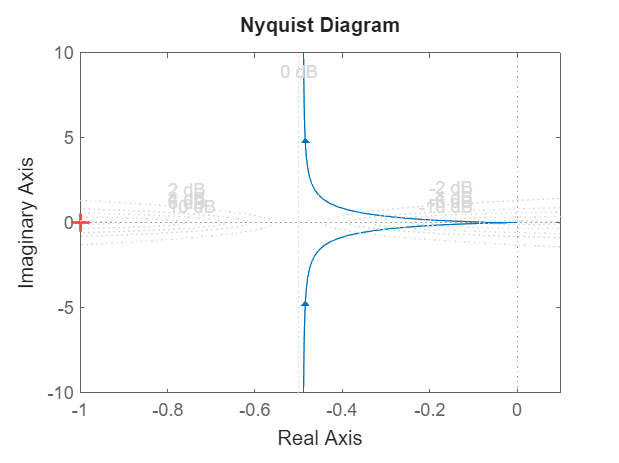


nyquist(L)
grid on

Budući da su svi polovi i nule u lijevoj poluravnini sustav je stabilan.

% Željena vlaga [%]
desired_moisture = 70

desired_moisture = 70

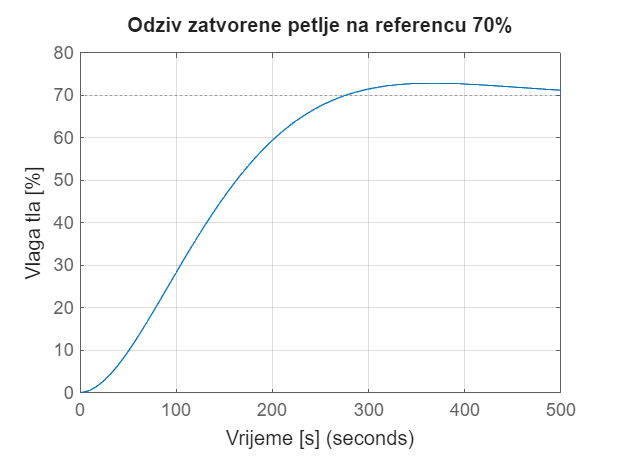


figure;
step(desired_moisture*T_pid, 500);
grid on;
title('Odziv zatvorene petlje na referencu 70%');
xlabel('Vrijeme [s]');
ylabel('Vlaga tla [%]');


info = stepinfo(70*T_pid);

fprintf('Vrijeme stabilizacije: %.2f s\n', info.SettlingTime);

Vrijeme stabilizacije: 485.70 s


fprintf('Nadvišenje: %.2f %%\n', info.Overshoot);

Nadvišenje: 4.06 %


### **Usporedba s prijenosom bez povratne veze**

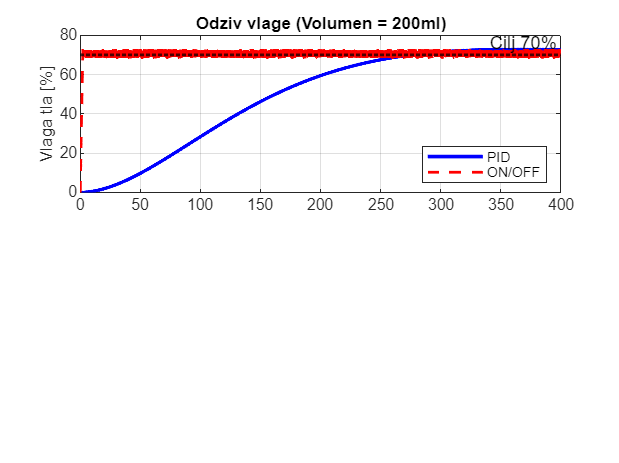


desired_moisture = 70;   % Ciljana vlaga [%]
dt = 0.1;                % Korak simulacije [s]
t_sim = 0:dt:400;        % Vremenska os (produžena na 400s zbog tromosti 200ml)

kp_fizika = 150;          % Pojačanje procesa
u_max = 500;               % Max protok pumpe [ml/s]

B_koef = (kp_fizika * k12 / V2); 
A_koef = (k12 + ke);

[y_pid, t_pid] = step(desired_moisture * T_pid, t_sim);


%% --- ON/OFF REGULATOR ---
y_onoff = zeros(size(t_sim));
u_onoff = zeros(size(t_sim));
histereza = 0.5; 

for k = 2:length(t_sim)
    % Logika s histerezom
    if y_onoff(k-1) < (desired_moisture - histereza)
        u_onoff(k) = u_max;
    elseif y_onoff(k-1) > (desired_moisture + histereza)
        u_onoff(k) = 0;
    else
        u_onoff(k) = u_onoff(k-1);
    end

    % Euler diskretizacija
    dydt = B_koef * u_onoff(k) - A_koef * y_onoff(k-1);
    y_onoff(k) = y_onoff(k-1) + dydt * dt;
end

%% --- CRTANJE USPOREDBE ---
figure('Name', 'Analiza navodnjavanja: PID vs ON/OFF', 'Color', 'w');

% 1. GRAF: Odziv vlage
subplot(2,1,1);
plot(t_pid, y_pid, 'b', 'LineWidth', 2); hold on;
plot(t_sim, y_onoff, 'r--', 'LineWidth', 1.5);
yline(desired_moisture, 'k:', 'Cilj 70%', 'LineWidth', 1.5);
grid on;
ylabel('Vlaga tla [%]');
legend('PID', 'ON/OFF', 'Location', 'southeast');
title(['Odziv vlage (Volumen = ', num2str(V2), 'ml)']);

Sustav bez PID regulatora ne postiže zadanu referencu zbog stacionarne pogreške karakteristične za sustave bez integracijskog djelovanja, što rezultira stabilizacijom izlaza na približno 58% umjesto željenih 70%.

## Prema Ziegler-Nicholsu PID parametri

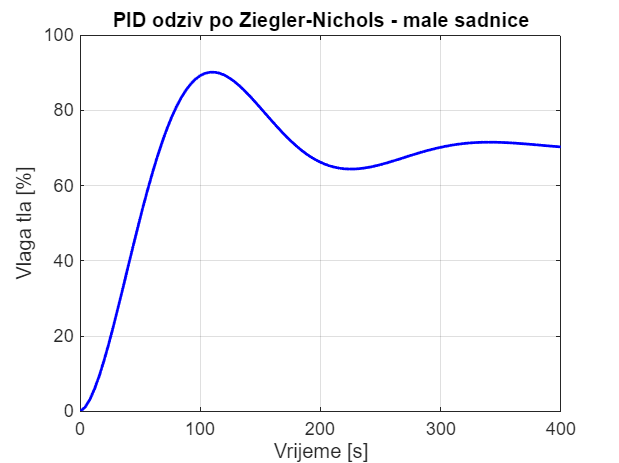

% Parametri Ziegler-Nichols, za svaki slucaj se računa ispočetka
Kp = 4.25;
Ki = 0.28;   % s
Kd = 6.26;    % s

Gr_z = pid(Kp, Ki, Kd);

% Zatvorena petlja
T_pid = feedback(Gr_z*G0,1);

% Željena vlaga
desired_moisture = 70;  % %

% Odziv
[y,t] = step(T_pid, 400);
y = y * desired_moisture;

figure;
plot(t,y,'b','LineWidth',1.5);
grid on;
title('PID odziv po Ziegler-Nichols - male sadnice');
xlabel('Vrijeme [s]');
ylabel('Vlaga tla [%]');


% Karakteristike odziva
info_pid = stepinfo(y,t,desired_moisture);
fprintf('PID Regulacija - vrijeme stabilizacije: %.2f s, nadvišenje: %.2f %%\n', ...
    info_pid.SettlingTime, info_pid.Overshoot);

PID Regulacija - vrijeme stabilizacije: 356.74 s, nadvišenje: 28.80 %
